# Trim, Linearise and design a Control system for the 3D Inverted pendulum model:

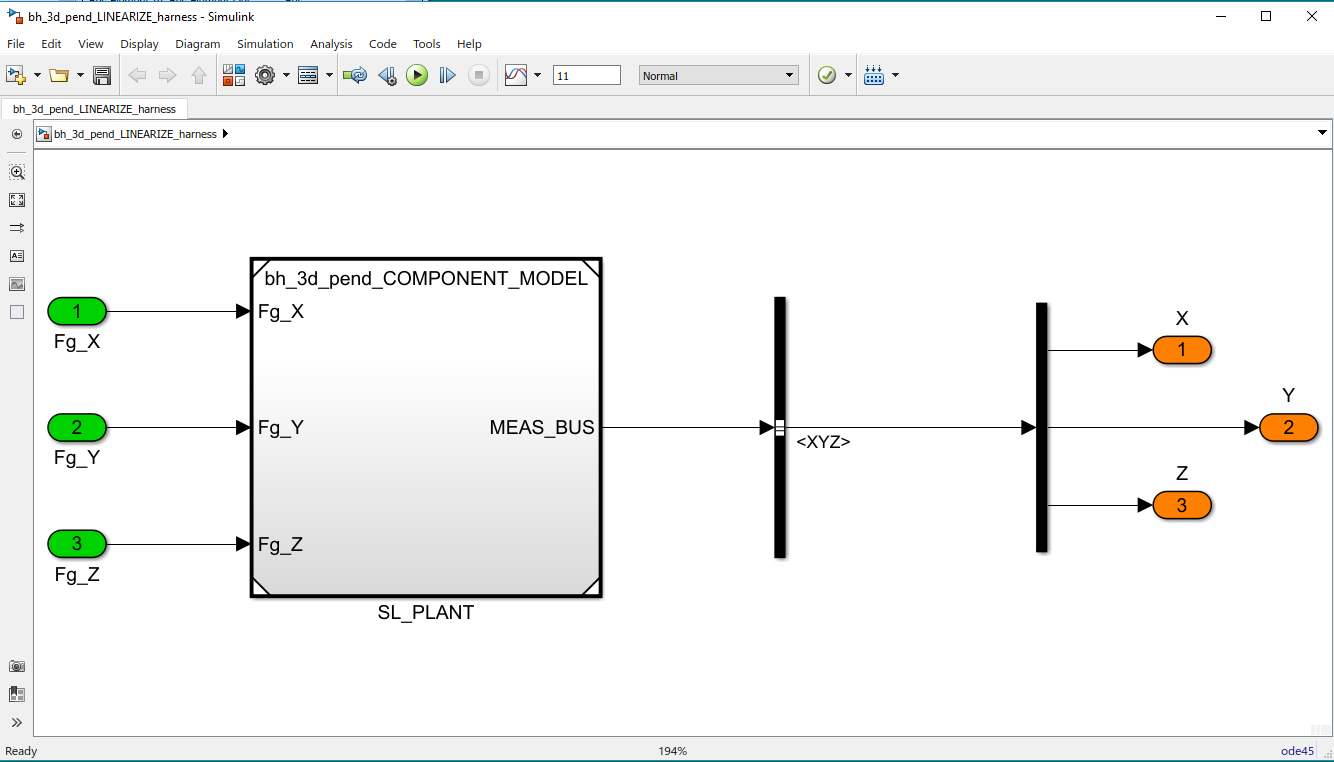

In this task we're going to linearise our **Simulink** inverted pendulum model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the pendulum.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the pendulum model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Regulator (LQR) technique.

`Bradley Horton : 28-Jun-2017, bradley.horton@mathworks.com.au`

# 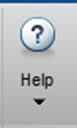 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_params_for_3D_pend_control_linearise
whos

  Name                     Size            Bytes  Class           Attributes

  Hx                       1x1                 8  double                    
  Hy                       1x1                 8  double                    
  Hz                       1x1                 8  double                    
  Lx                       1x1                 8  double                    
  Ly                       1x1                 8  double                    
  Lz                       1x1                 8  double                    
  MEAS_BUS_SL_3D_PEND      1x1               597  Simulink.Bus              
  M_cart                   1x1                 8  double                    
  Pos_list                 1x1               381  Simulink.Bus              
  Tv_Z                     1x1                 8  double                    
  Vel_list                 1x1               405  Simulink.Bus              
  g                        1x1                 8  double                   

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_3d_pend_LINEARIZE_harness';
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)

opspec =  Operating point specification for the Model bh_3d_pend_LINEARIZE_harness.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
    x    Known    SteadyState    Min     Max    dxMin    dxMax
    _    _____    ___________    ____    ___    _____    _____

(1.) Phi
    0    false       true        -Inf    Inf    -Inf      Inf 
(2.) Theta
    0    false       true        -Inf    Inf    -Inf      Inf 
(3.) 

**NOTE that the signals being processed by each integrator are these: **$q_k = \{ \Phi, \Theta, \psi, {^GX}, {^GY}, {^GZ} \}$

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

ans = 1×12 logical array
   1   1   1   1   1   1   1   1   1   1   1   1


Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)

opreport =  Operating point search report for the Model bh_3d_pend_LINEARIZE_harness.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min     x    Max    dxMin        dx         dxMax
    ____    _    ___    _____    ___________    _____

(1.) Phi
    -Inf    0    Inf      0                0      0  
(2.) Theta
    -Inf    0    Inf      0                0      0  
(3.) 

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op)

my_LIN_PLANT =
 
  A = 
              Theta      Psi        X        Y        Z  Theta_D    Psi_D
   Theta          0        0        0        0        0        1        0
   Psi            0        0        0        0        0        0        1
   X              0        0        0        0        0        0        0
   Y              0        0        0        0        0        0        0
   Z              0        0        0        0        0        0        0
   Theta_D    34.98        0        0        0        0        0        0
   Psi_D          0    34.98        0        0        0        0        0
   X_D       -1.857        0        0        0        0        0        0
   Y_D            0    1.857        0        0        0        0        0
   Z_D            0        0        0        0        0        0        0
 
                X_D      Y_D      Z_D
   Theta          0        0        0
   Psi            0        0        0
   X              1        0        0
   Y    

Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 3×1 cell array
    {'bh_3d_pend_LINEARIZE_harness/Fg_X'}
    {'bh_3d_pend_LINEARIZE_harness/Fg_Y'}
    {'bh_3d_pend_LINEARIZE_harness/Fg_Z'}


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName

ans = 3×1 cell array
    {'X'}
    {'Y'}
    {'Z'}


and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 10×1 cell array
    {'Theta'  }
    {'Psi'    }
    {'X'      }
    {'Y'      }
    {'Z'      }
    {'Theta_D'}
    {'Psi_D'  }
    {'X_D'    }
    {'Y_D'    }
    {'Z_D'    }


Get ready for a simulation:

x0 = [20*pi/180, 20*pi/180, 0,0,0,  zeros(1,5)];

Check that the linearised system is controllable: 

A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;
D = my_LIN_PLANT.D;

co = ctrb(A,B);
if(rank(co) ~= size(A,1) )
    error('###_ERROR: the system is NOT controllable');
end

And close the model:

close_system(model)

## Control design:

We'll use the approach described by the LQI() function, ie::

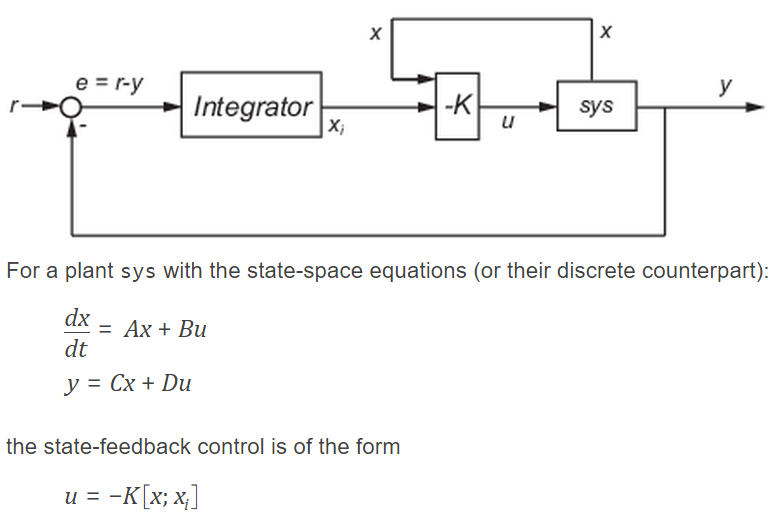

Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

- alternatively consider using place() to manually specify the position of the poles

% Q = 55*diag(ones(1, Nx+Nu));
% R =  1*diag(ones(1, Nu));
Q = 55*diag(ones(1, Nx+Ny));
R =  1*diag(ones(1, Nu));
[K,~,~] = lqi(my_LIN_PLANT,Q,R,[])

K =   -78.3611    0.0000  -17.2276   -0.0000    0.0000  -15.8788    0.0000  -16.3016   -0.0000    0.0000    7.4162    0.0000   -0.0000
   -0.0000   78.3611   -0.0000  -17.2276   -0.0000   -0.0000   15.8788   -0.0000  -16.3016   -0.0000    0.0000    7.4162    0.0000
   -0.0000    0.0000   -0.0000   -0.0000   13.9275   -0.0000    0.0000   -0.0000   -0.0000    9.3697    0.0000    0.0000   -7.4162


What does the gain matrix K, look like?

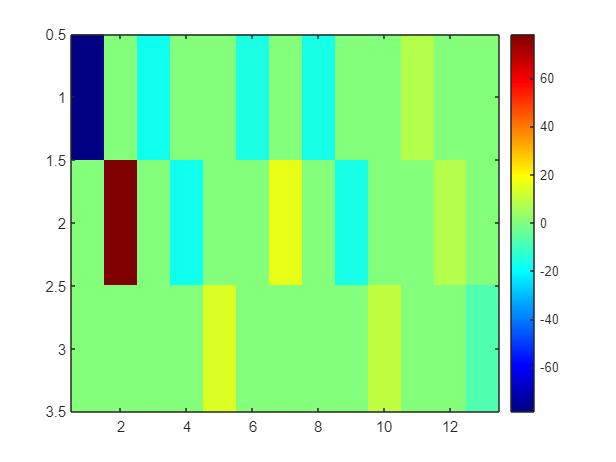

hfig = figure;
colormap(hfig,jet)
imagesc(K); colorbar

Now test the design using ONLY the linearised plant:

% open_system('bh_3d_pend_TEST_LINEAR_SYS_CONT_DESIGN')

Now save the results:

RESULTS_FILE_NAME = 'bh_CONT_DES_RESULTS.mat';
the_state_names =  my_LIN_PLANT.StateName;
K_LAW           = K;

save(RESULTS_FILE_NAME, 'K_LAW', 'the_state_names')